% Progetto - Chiari
clear
close all
clc

Questions & Tips

3) Lunghezza windows

4) Scelta features (dominio tempi e frequenze)

5) Analisi e classificazione su ogni soggetto e tra soggetti diversi

6) Mettere i 3 accelerometri insieme e valutare scelte di un

   accelerometro piuttosto che un altro e/o errori

7) Mettere anche ECG e PPG insieme e classificare

Preprocessing

IMU on the ankle, ECG on the chest, PPG on the wrist

generazione report

import mlreportgen.report.*;
import mlreportgen.dom.*;

doctype = "pdf";
rpt = Report("Risultati",doctype);

create title page

tp = TitlePage("Title","Ageing project","Subtitle","Results");
add(rpt,tp);

Create chapter 1 and section 1

ch1 = Chapter("Title");
s1 = Section("blablabla");
p1 = Text(" "); % qui scriviamo un breve pezzo di commenti su cosa vedremo

fig1 = Figure(plot(t,p,'bo'));
axis([]);
title(""); % title of the figure
%xlabel or ylabel

add(s1,p1);
add(s1,fig1);
add(ch1,s1);

Create section 2 chapter 1

s2 = Section("Title");
p1 = ("");
p2 = ("");

c(:,1) = % tabella da analizzare
c(:,2) = % seconda riga tabella da analizzare

tbl = BaseTable(c);
tbl.TableWidth = "5in";
tbl.Title = "";

add(s2,p1);
add(s2,p2);
add(s2,tbl);
add(ch1,s2);
add(rpt,ch1);

close and view the report

close(rpt);
rptview(rpt);

%subject = ["ALESSANDRA","ALEX","CHIARA","CLAUDIA","DANIELE","ELENA","FEDERICA","FRANCESCO","MATTEO_G","GAETANO","GIORGIA","LUCA","DANIELE_G","MASSIMO","MATTEO"]; % MANCA SOPHIE
subject = {"ALE","ALEX","CHIARA","CLAUDIA","DANIELE_PA","ELENA","FEDERICA","FRANCESCO","MATTEO_G","GAETANO","GIORGIA","LUCA","DANIELE_G","MASSIMO","MATTEO_F"};

[indx,tf] = listdlg('ListString',subject);
subject = convertContainedStringsToChars(subject);
sensor = ["IMU","ECG","PPG"];

%%
n = length(subject);
for i = 1:n
    for j = 1:3
        stringa = strcat(sensor(j),"_",subject(i),'.mat');
        dati{i,j} = importdata(stringa);
    end
end

FS = 128;

tempi_task = zeros(n,10);

for i = 1:n
    [date_min(i), date_max(i)] = istanteiniziofine(dati{i,1}, dati{i,2}, dati{i,3}, FS, i);
    [dati{i,1}, dati{i,2}, dati{i,3}] = tempo_interesse(dati{i,1}, dati{i,2}, dati{i,3}, date_min(i), date_max(i));
    dati{i,1}.imu_Timestamp_Unix_CAL = [0:length(dati{i,1}.imu_Timestamp_Unix_CAL)-1]/FS;
    dati{i,2}.S_83B4_ECG_Timestamp_Unix_CAL = [0:length(dati{i,2}.S_83B4_ECG_Timestamp_Unix_CAL)-1]/FS;
    dati{i,3}.S_COD4_PPG_Timestamp_Unix_CAL = [0:length(dati{i,3}.S_COD4_PPG_Timestamp_Unix_CAL)-1]/FS;
    tempi_task(i,:) = divisione_task(dati{i,1}, FS, i); % casi particolari per Luca
end

for i = 1:n % Solo per classificazione, non per analisi tra IMU, ECG e PPG
    [dati{i,1}, dati{i,2}, dati{i,3}] = filtraggio(dati{i,1}, dati{i,2}, dati{i,3}, FS);
end

fields = {'S_83B4_ECG_ECG_EMG_Status1_CAL', 'S_83B4_ECG_ECG_EMG_Status2_CAL', 'S_83B4_ECG_ECG_LA_RA_24BIT_CAL', 'S_83B4_ECG_ECG_LL_LA_24BIT_CAL', 'S_83B4_ECG_ECG_LL_RA_24BIT_CAL', 'S_83B4_ECG_ECG_Vx_RL_24BIT_CAL'};

for i = 1:n
    dati_acc{i,1} = dati{i,1};
    dati_acc{i,2} = rmfield(dati{i,2},fields);
    dati_acc{i,3} = rmfield(dati{i,3},"S_COD4_PPG_PPG_A13_CAL");
end


ECG_DATA_EXTRACTION

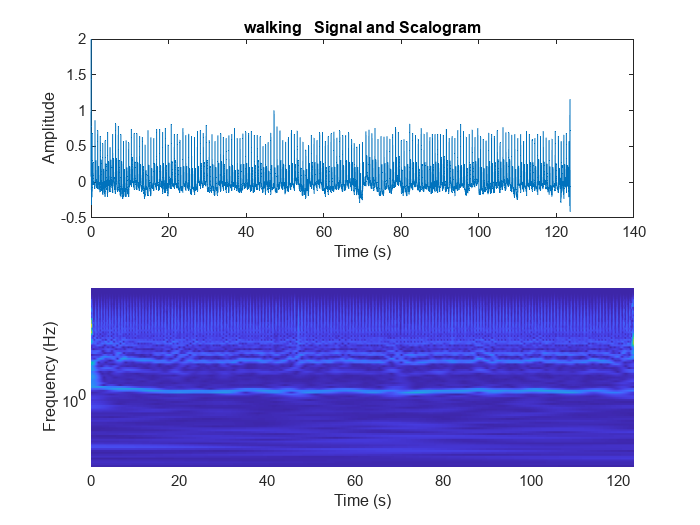

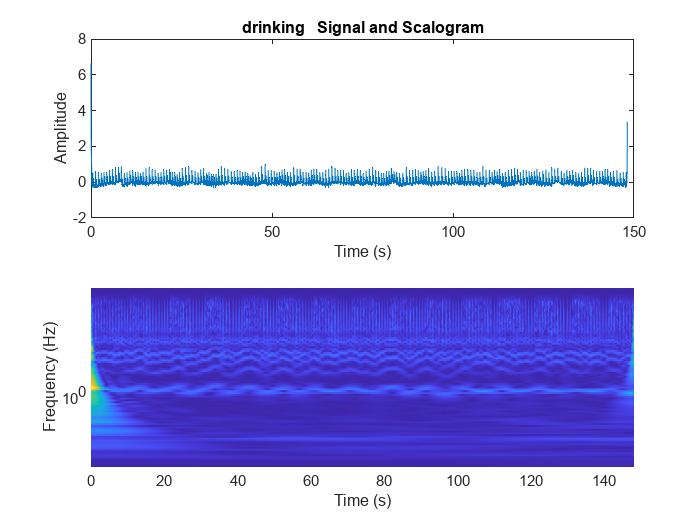

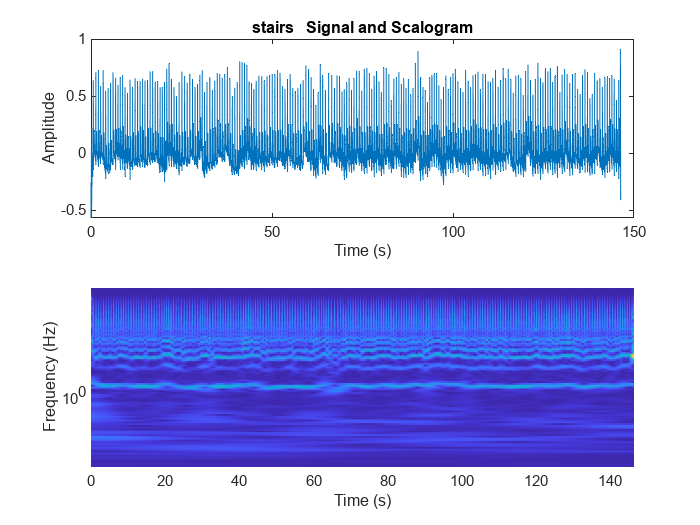

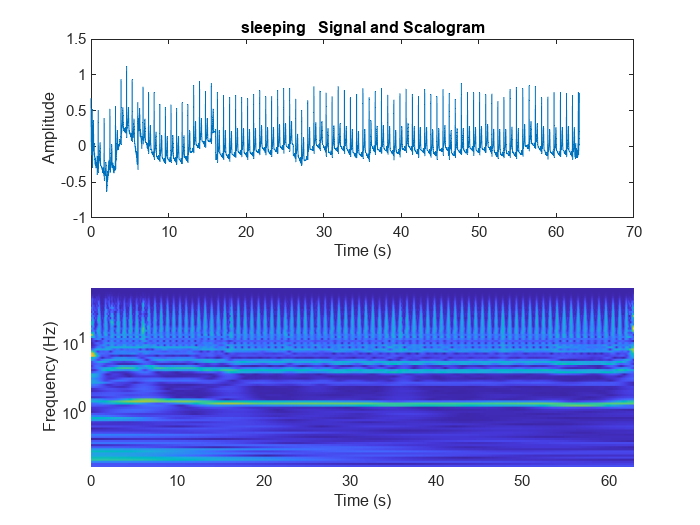

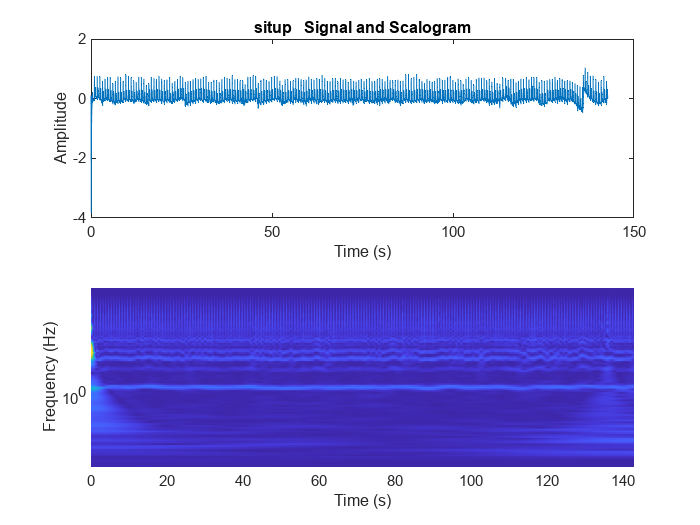


for i = 1:size(dati,1)
    ecg_data = dati{i,2};
    LA_RA = ecg_data.S_83B4_ECG_ECG_LA_RA_24BIT_CAL;
    LL_LA = ecg_data.S_83B4_ECG_ECG_LL_LA_24BIT_CAL;
    LL_RA = ecg_data.S_83B4_ECG_ECG_LL_RA_24BIT_CAL;
    %time_total=datetime(ecg_data.S_83B4_ECG_Timestamp_Unix_CAL,'convertfrom','posixtime','timezone','Europe/Rome');
    time_total = ecg_data.S_83B4_ECG_Timestamp_Unix_CAL;
    val = {[LA_RA LL_LA LL_RA time_total']};
    ECG_SUB{i,1} = val;

    if tempi_task(i,10) > time_total(end)*128
        tempi_task(i,10) = time_total(end)*128;
        kk(i) = i;
    end

    zz = intersect(round(time_total*128,-1),round(tempi_task(i,:),-1));
    time_refe{i,1} = zz;

end

%%
%ECG_DATA_PROCESSING

close all

fps = FS;
fc = 40;
fc_h = 0.1;
[b,a] = butter(3,fc/(fps/2),'low');
[d,c] = butter(3,fc_h/(fps/2),'high');
L = length(subject);

for i = 1:L %size(subject,2)
    LA_RA_n = ECG_SUB{i,1}{1,1}(:,1);
    LL_LA_n = ECG_SUB{i,1}{1,1}(:,2);
    LL_RA_n = ECG_SUB{i,1}{1,1}(:,3);
    time_s = ECG_SUB{i,1}{1,1}(:,4);
    t = time_s(1);
    time_s = (time_s-t)/1000;
    timef = time_s*fps/1000;
    LA_RA_n = LA_RA_n-mean(LA_RA_n);
    LL_LA_n = LL_LA_n-mean(LL_LA_n);
    LL_RA_n = LL_RA_n-mean(LL_RA_n);
    Len = length(time_s);
    
    for j = 10*fps:10*fps:Len-2*fps
        LL_RA_n(j+1-10*fps:j) = detrend(LL_RA_n(j+1-10*fps:j));
        LL_LA_n(j+1-10*fps:j) = detrend(LL_LA_n(j+1-10*fps:j));
        LA_RA_n(j+1-10*fps:j) = detrend(LA_RA_n(j+1-10*fps:j));
    end

    LL_LA_n = filtfilt(b,a,LL_LA_n);
    LL_RA_n = filtfilt(b,a,LL_RA_n);
    LA_RA_n = filtfilt(b,a,LA_RA_n);
    LL_LA_n = filtfilt(d,c,LL_LA_n);
    LL_RA_n = filtfilt(d,c,LL_RA_n);
    LA_RA_n = filtfilt(d,c,LA_RA_n);
    new_val = [LL_LA_n,LL_RA_n,LA_RA_n,time_s];
    ECG_SUB_new{i,1} = new_val;
    
end

%% TASK SPLIT
for i = 1:size(ECG_SUB_new,1)
    task = ["walking","drinking","stairs","sleeping","situp"];
    derivation = ["LL_LA","LL_RA","LA_RA"];

    for j = 1:3
        signal = ECG_SUB_new{i,1}(:,j);
        [walking,drinking,stairs,sleeping,situp] = task_generator(signal,tempi_task(i,:));
        ECG_SUBsplit{i,1}.derivation(j) = struct('walking',walking,"drinking",drinking,"stairs",stairs,"sleeping",sleeping,"situp",situp);
    end
end

%% CORR.INDEX
s = indx;

VX_sleepi = (ECG_SUBsplit{s, 1}.derivation(1).sleeping+ECG_SUBsplit{s, 1}.derivation(2).sleeping+ECG_SUBsplit{s, 1}.derivation(3).sleeping)/3;
VX_sleep = VX_sleepi(2*fc:size(VX_sleepi,1)-2*fc);
half = round(length(VX_sleep)/2,-1);
first_part_sleep = VX_sleep(fc:half);
LenSle = length(first_part_sleep);
second_part_sleep = VX_sleep(end:-1:length(VX_sleep)-LenSle+1);
[R,P] = corrcoef(first_part_sleep,second_part_sleep);

freq = [1:length(ECG_SUB_new{s,1}(:,4))]*fc/length(ECG_SUB_new{s,1}(:,4));
freq_s = [1:size(VX_sleep,1)]*fc/size(VX_sleep,1);

% SLEEP
%VX_sleep=(ECG_SUBsplit{s, 1}.derivation(1).sleeping+ECG_SUBsplit{s, 1}.derivation(2).sleeping+ECG_SUBsplit{s, 1}.derivation(3).sleeping)/3;
LS = length(VX_sleep);
VX_sleepf = fft(VX_sleep,LS);

% WALK
VX_walki = (ECG_SUBsplit{s, 1}.derivation(1).walking+ECG_SUBsplit{s, 1}.derivation(2).walking+ECG_SUBsplit{s, 1}.derivation(3).walking)/3;
VX_walk = VX_walki(30*FS:30*FS+LS);
VX_walkf = fft(VX_walk,LS);

% STAIRS
VX_stairsi = (ECG_SUBsplit{s, 1}.derivation(1).stairs+ECG_SUBsplit{s, 1}.derivation(2).stairs+ECG_SUBsplit{s, 1}.derivation(3).stairs)/3;
VX_stairs = VX_stairsi(30*FS:30*FS+LS);
VX_stairsf = fft(VX_stairs,LS);

% SIT UP
VX_situp = (ECG_SUBsplit{s, 1}.derivation(1).situp+ECG_SUBsplit{s, 1}.derivation(2).situp+ECG_SUBsplit{s, 1}.derivation(3).situp)/3;
VX_situpf = fft(VX_situp);

% DRINK
VX_drink = (ECG_SUBsplit{s, 1}.derivation(1).drinking+ECG_SUBsplit{s, 1}.derivation(2).drinking+ECG_SUBsplit{s, 1}.derivation(3).drinking)/3;
VX_drinkf = fft(VX_drink);

VX_taskF = {VX_walkf,VX_drinkf,VX_stairsf,VX_sleepf,VX_situpf};
VX_task = {VX_walki,VX_drink,VX_stairsi,VX_sleepi,VX_situp};

figure()
for i = 1:size(task,2)
    freq_t = [1:length(VX_taskF{i})]*fps/length(VX_taskF{i});
    freq_task{i,1} = {freq_t};
    log_VX = 20*log10(abs(VX_taskF{i}));
    subplot(5,1,i)
    stem(freq_t(1:round(end/2)),log_VX(1:round(end/2)),'filled');
    legend(task(i));
    ylim([0,100]);
end

P;
R;
s;

%%
% WN1=[0.1 15]/(FS/2)
% WN2=[15 30]/(FS/2)
% WN3=[30 45]/(FS/2)
% [b0,a0]=butter(5,WN1,'bandpass')
% [b1,a1]=butter(5,WN2,'bandpass')
% [b2,a2]=butter(5,WN3,'bandpass')
% for i=1:size(task,2)
%     vx_temp=VX_task{:,i};
%     freq_t=freq_task{i,1}{1,:};
%     VX_00_15=filtfilt(b0,a0,vx_temp);
%     VX_15_30=filtfilt(b1,a1,vx_temp);
%     VX_30_45=filtfilt(b2,a2,vx_temp);
%     VX_30_45f=fft(VX_30_45);
%     VX_15_30f=fft(VX_15_30);
%     VX_00_15f=fft(VX_00_15);
%     figure(i)
%     title(task(i))
%     subplot(3,1,1)
%     plot(freq_t,20*log10(abs(VX_00_15f)))
%     subplot(3,1,2)
%     plot(freq_t,20*log10(abs(VX_15_30f)))
%     subplot(3,1,3)
%     plot(freq_t,20*log10(abs(VX_30_45f)))
% end
% s

%%
close all

for i = 1:size(task,2)
    DELTAF = length(freq_task{i,1}{1,:})/FS;
    FREQ_delta01_15 = [0.1:1/DELTAF:15];
    k0115 = length(FREQ_delta01_15);
    VX_01_15 = VX_taskF{:,i}(1:k0115);
    VX_01_15s{i,1} = VX_01_15;
    VX_01_15 = 20*log10(abs(VX_01_15));
    
    FREQ_delta15_30 = [15:1/DELTAF:30];
    k15_30 = length(FREQ_delta15_30);
    VX_15_30 = VX_taskF{:,i}(k0115:k0115+k15_30-1);
    VX_15_30s{i,1} = VX_15_30;
    VX_15_30 = 20*log10(abs(VX_15_30));
    
    FREQ_delta30_45 = [30:1/DELTAF:45];
    k30_45 = length(FREQ_delta30_45);
    VX_30_45 = VX_taskF{:,i}(k0115+k15_30:k0115+k15_30+k30_45-1);
    VX_30_45s{i,1} = VX_30_45;
    VX_30_45 = 20*log10(abs(VX_30_45));
    
    figure(i)
    plot(FREQ_delta01_15,VX_01_15)
    hold on
    plot(FREQ_delta15_30,VX_15_30)
    hold on
    plot(FREQ_delta30_45,VX_30_45)
    title(task(i))

end

%%
[RWS15_30,PWS15_30] = corrcoef(abs(VX_15_30s{1,1}),abs(VX_15_30s{4,1}));
[RWS01_15,PWS01_15] = corrcoef(abs(VX_01_15s{1,1}),abs(VX_01_15s{4,1}));
[RWS30_45,PWS30_45] = corrcoef(abs(VX_30_45s{1,1}),abs(VX_30_45s{4,1}));
%%
[RWSt15_30,PWSt15_30] = corrcoef(abs(VX_15_30s{1,1}),abs(VX_15_30s{3,1}));
[RWSt01_15,PWSt01_15] = corrcoef(abs(VX_01_15s{1,1}),abs(VX_01_15s{3,1}));
[RWSt30_45,PWSt30_45] = corrcoef(abs(VX_30_45s{1,1}),abs(VX_30_45s{3,1}));
%%
for i = 1:length(VX_30_45s{4,1})
    EW = sum(abs(VX_30_45s{4,1}(i).^2));
end

powbp30_45w = bandpower(VX_30_45s{1,1},FS,[30 45]);
powbp15_30w = bandpower(VX_30_45s{1,1},FS,[15 30]);
powbp01_15w = bandpower(VX_30_45s{1,1},FS,[1 15]);

powbp30_45st = bandpower(VX_30_45s{3,1},FS,[30 45]);
powbp15_30st = bandpower(VX_30_45s{3,1},FS,[15 30]);
powbp01_15st = bandpower(VX_30_45s{3,1},FS,[1 15]);

%%
for i = 1:size(task,2)
    tt_task = [1 : length(VX_task{1,i})]/fps;
    
    % PULIZIA DEL SEGNALE
    smoothECG = sgolayfilt(VX_task{1,i},7,21);
    
    figure()
    subplot(211)
    plot(tt_task,VX_task{1,i},'b',tt_task,smoothECG,'r')
    grid on
    axis tight
    xlabel('Samples')
    ylabel('Voltage(mV)')
    legend('Noisy ECG Signal','Filtered Signal')
    title('Filtering Noisy ECG Signal of ' + task(i));
    
    subplot(212)
    plot(tt_task,smoothECG)
    grid on
    axis tight
    title('ECG ' + task(i))

    [R_pks,R_locs] = findpeaks(smoothECG,'MinPeakDistance',0.5 * FS); 
    R_locs_S{i,1} = R_locs;
    R_pks_S{i,1} = R_pks;
    figure
    plot(tt_task,smoothECG)
    hold on
    plot(tt_task(R_locs),smoothECG(R_locs),'*')
    title(task(i)+" R PEAKS")
    
    RR_ist = (R_locs(2:end) - R_locs(1:end-1)) * 1/FS;
    t_RR_ist = cumsum(RR_ist); 
    t_RR_ist = t_RR_ist - t_RR_ist(1) * ones(size(t_RR_ist(1)));
    HR_ECG = mean(60 ./ RR_ist);
    SDNN_ECG = std(RR_ist) *1000;
    RMSSD_ECG = sqrt(mean((RR_ist(2:end) - RR_ist(1:end-1)).^2)) * 1000;
    RR_ms = RR_ist * 1000; 
    RR_demean = RR_ms - mean(RR_ms)*ones(size(RR_ms));
    RR_ms = RR_ist * 1000; 
    RR_demean = RR_ms - mean(RR_ms)*ones(size(RR_ms));
    
    % Detrend
    RR_detrend = detrend(RR_demean,'linear');
    
    % Interpolation
    F_resample = 4; 
    T_resample = 1/F_resample; 
    t_res = t_RR_ist(1):T_resample:t_RR_ist(end); 
    RR_ist_resample = interp1(t_RR_ist,RR_detrend,t_res);

    % High pass filter
    ordr     = 6;
    ft       = 0.02; %[Hz] Cutoff frequency
    Wn_HP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_HP,'high');
    RR_HP    = filtfilt(b,a,RR_ist_resample);
    
    % Low pass filter
    ordr     = 6;
    ft       = 0.4; %[Hz] Cutoff frequency
    Wn_LP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_LP);
    RR_filt  = filtfilt(b,a,RR_HP);
    
    % window = 5*60*F_resample;
    L = length(RR_filt); 
    NFFT = 2^nextpow2(L); % Vollmer M. 2015 "A robust, simple and reliable measure of HRV using relative RR intervals"
    [PSD,F] = pwelch(RR_filt,[],[],NFFT,4);
    
    figure
    plot(F,PSD)
    title(task(i))
    
    LF = [0.04 0.15];
    HF = [0.15 0.4];
    
    iLF = (round(F,2) >= LF(1)) & (round(F,2) <= LF(2));
    aLF  = trapz(F(iLF),PSD(iLF));
    
    iHF = (round(F,2) >= HF(1)) & (round(F,2) <= HF(2));
    aHF  = trapz(F(iHF),PSD(iHF));
    
    i_TP = (round(F,2) >= LF(1)) & (round(F,2) <= HF(2)); 
    TP   = trapz(F(i_TP),PSD(i_TP));
    
    % Normalized values of the spectral bands
    nu_LF = aLF / TP * 100; 
    nu_HF = aHF / TP * 100;
    
    figure
    plot(F,PSD)
    xlabel('Frequency [Hz]'), ylabel('PSD [ms^2]')
    hold on 
    area(F(iLF),PSD(iLF))
    area(F(iHF),PSD(iHF))
    title(task(i))
    LFHF_ratio_ECG(i) = aLF/aHF;
end

%%
close all
for i = 1:size(task,2)
    time_t = [1:length(VX_task{i})];
    [cfs_ecg{i},freq_c] = cwt(VX_task{i},"bump",fps);
    tms = ((0:numel(time_t)-1)/fps);
    
    figure
    subplot(2,1,1)
    plot(tms,VX_task{i})
    title(task(i)+"   Signal and Scalogram")
    xlabel("Time (s)")
    ylabel("Amplitude")
    subplot(2,1,2)
    surface(tms,freq_c,abs(cfs_ecg{i}));
    axis tight
    shading flat
    colormap("default")
    xlabel("Time (s)")
    ylabel("Frequency (Hz)")
    set(gca,"yscale","log")
end

pause

%%
%pause
close all

Ppg = dati{indx,3}.S_COD4_PPG_PPG_A13_CAL;

N = length(Ppg);
time_total = 0:1/FS:(N-1)/FS;
order = 3;
cutF = 5;
[N,D] = butter(order, 2*cutF/FS);
PPG = filtfilt(N, D, zscore(detrend(Ppg)));

if tempi_task(indx,10) > time_total(end)*128
    tempi_task(indx,10) = time_total(end)*128;
end

[walking,drinking,stairs,sleeping,situp] = task_generator(PPG,tempi_task(indx,:));
PPG_SUBsplit = {walking,drinking,stairs,sleeping,situp};  %%struct('walking',walking,"drinking",drinking,"stairs",stairs,"sleeping",sleeping,"situp",situp);

sleeping_new = sleeping(5*FS:end-3*FS);
walking_cut1 = walking(30*FS:end-3*FS);
walking_cut = walking_cut1(1:length(sleeping_new));
lms = dsp.LMSFilter;
[walking_new,err_walking,wts_walking] = lms(walking_cut,sleeping_new);
f_walking = [1:length(walking)]*FS/length(walking);

figure()
plot([1:length(walking_new)],walking_new)
hold on
plot([1:length(walking_cut)],walking_cut)
legend('filtered LMS signal','normal signal')

figure()
walking_f=fft(walking)

walking_f = 1.0e+03 *

  -0.3702 + 0.0000i
  -0.0697 + 0.1785i
   0.1625 + 0.5618i
  -0.4348 - 0.5386i
   0.9925 - 0.1673i
   0.1801 - 0.3936i
   0.2280 + 0.4757i
   0.6980 - 0.6255i
   0.1848 - 0.8880i
   0.4325 - 1.5959i


plot(f_walking, walking_f)


%%
for i = 1:size(task,2)
    PPG    = PPG_SUBsplit{1,i};
    N_PPG  = length(PPG); 
    fs_PPG = 128; % [Hz]
    Ts_PPG = 1/fs_PPG; % [s]
    t_PPG  = (0:1:N_PPG-1) * Ts_PPG;
    [sysfeet_pks,sysfeet_locs] = findpeaks(PPG,'MinPeakDistance',0.5 * fs_PPG); 
    sysfeet_locs_S{i,1}=sysfeet_locs;
    sysfeet_pks_S{i,1}=sysfeet_pks;

    figure
    plot(t_PPG,PPG)
    hold on
    plot(t_PPG(sysfeet_locs),PPG(sysfeet_locs),'*')
    title(task(i))

    IBI_ist   = (sysfeet_locs(2:end) - sysfeet_locs(1:end-1)) * Ts_PPG;
    t_IBI_ist = cumsum(IBI_ist);
    t_IBI_ist = t_IBI_ist - t_IBI_ist(1) * ones(size(t_IBI_ist(1)));
    
    figure
    %plot(t_RR_ist,RR_ist)
    title(task(i))
    %hold on
    plot(t_IBI_ist,IBI_ist)
    SDNN_PPG = std(IBI_ist) * 1000;
    RMSSD_PPG = sqrt(mean((IBI_ist(2:end) - IBI_ist(1:end-1)).^2)) * 1000;
    IBI_ms = IBI_ist * 1000;
    IBI_demean = IBI_ms - mean(IBI_ms)*ones(size(IBI_ms));

    % Detrend
    IBI_detrend = detrend(IBI_demean,'linear');

    % Interpolation
    F_resample = 4; 
    T_resample = 1/F_resample; 
    t_res = t_IBI_ist(1):T_resample:t_IBI_ist(end); 
    IBI_ist_resample = interp1(t_IBI_ist,IBI_detrend,t_res);

    % High pass filter
    ordr     = 6;
    ft       = 0.02; %[Hz] Cutoff frequency
    Wn_HP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_HP,'high');
    IBI_HP   = filtfilt(b,a,IBI_ist_resample);

    % Low pass filter
    ordr     = 6;
    ft       = 0.4; %[Hz] Cutoff frequency
    Wn_LP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_LP);
    IBI_filt = filtfilt(b,a,IBI_HP);
    
    window = 5*60*F_resample;
    L = length(IBI_filt); 
    NFFT = 2^nextpow2(L); % Vollmer M. 2015 "A robust, simple and reliable measure of HRV using relative RR intervals"
    [PSD,F] = pwelch(IBI_filt,[],[],NFFT,4);
    
    figure
    plot(F,PSD)
    
    iLF  = (round(F,2) >= LF(1)) & (round(F,2) <= LF(2));
    aLF  = trapz(F(iLF),PSD(iLF));
    
    iHF  = (round(F,2) >= HF(1)) & (round(F,2) <= HF(2));
    aHF  = trapz(F(iHF),PSD(iHF));
    
    i_TP = (round(F,2) >= LF(1)) & (round(F,2) <= HF(2)); 
    TP   = trapz(F(i_TP),PSD(i_TP));
    
    % Normalized values of the spectral bands
    nu_LF = aLF / TP * 100; 
    nu_HF = aHF / TP * 100;
    
    figure
    plot(F,PSD)
    xlabel('Frequency [Hz]'), ylabel('PSD [ms^2]')
    hold on 
    title(task(i))
    area(F(iLF),PSD(iLF))
    area(F(iHF),PSD(iHF))
    
    LFHF_ratio_PPG(i) = aLF/aHF;
end

%%
for i = 1:size(task,2)
    time_t = [1:length(PPG_SUBsplit{i})];
    [cfs_ppg{i},freq_c_ppg] = cwt(PPG_SUBsplit{i},"bump",fps);
    tms = ((0:numel(time_t)-1)/fps);
    
    figure
    subplot(2,1,1)
    plot(tms,PPG_SUBsplit{i})
    title(task(i)+"   Signal and Scalogram")
    xlabel("Time (s)")
    ylabel("Amplitude")
    subplot(2,1,2)
    surface(tms,freq_c_ppg,abs(cfs_ppg{i}));
    axis tight
    shading flat
    colormap("default")
    xlabel("Time (s)")
    ylabel("Frequency (Hz)")
    set(gca,"yscale","log")
end

[R_locs_S,sysfeet_locs_S]

ans = 5×2 cell array
    {169×1 double}    {170×1 double}
    {191×1 double}    {185×1 double}
    {215×1 double}    {214×1 double}
    { 82×1 double}    { 82×1 double}
    {198×1 double}    {198×1 double}


task

task = 1×5 string array
    "walking"    "drinking"    "stairs"    "sleeping"    "situp"


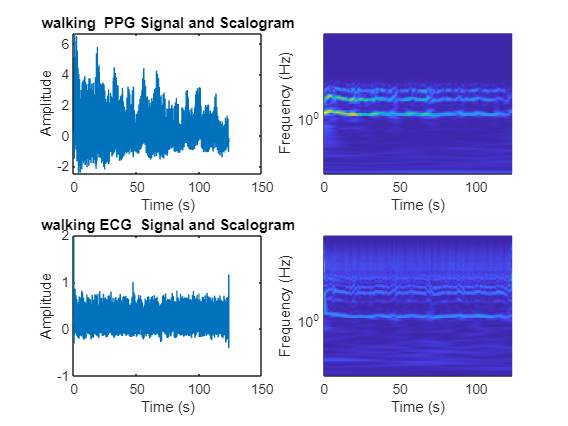

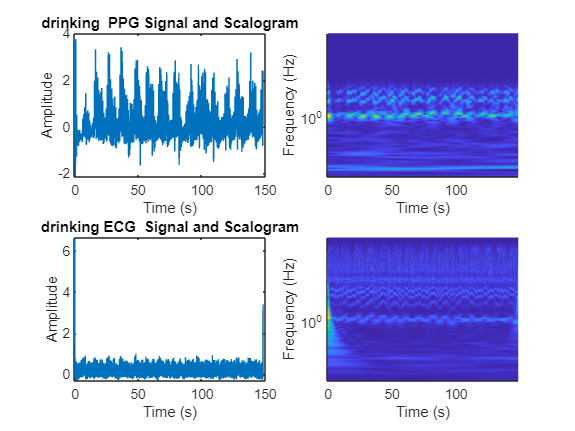

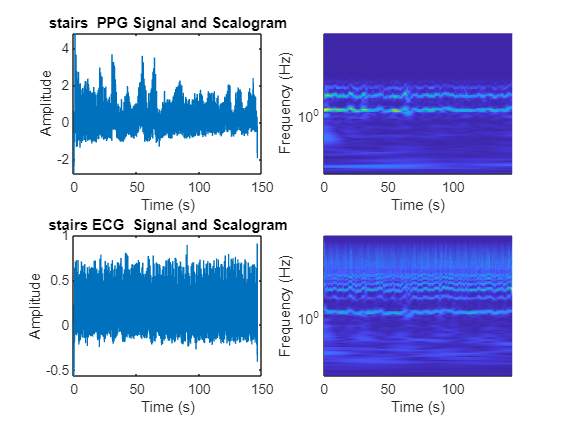

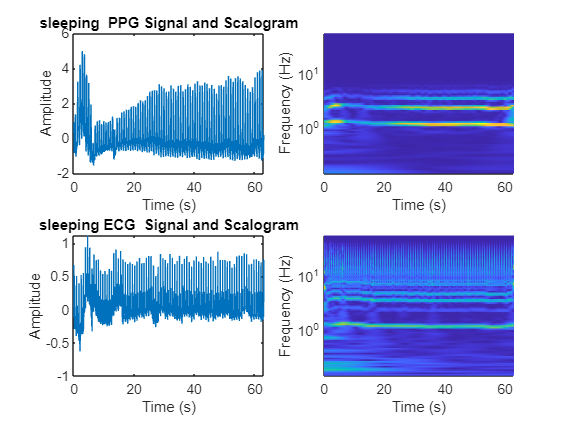

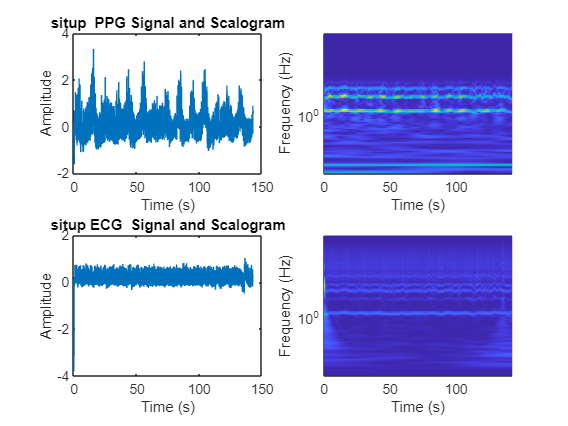


%%

close all
for v = 1:5
    ecg_p = ones(size(R_locs_S{v,1},1),1)*3;
    ppg_p = ones(size(sysfeet_locs_S{v,1},1),1);
    
    figure()
    plot(R_locs_S{v,1}/fc,ecg_p,'*')
    hold on
    plot(sysfeet_locs_S{v,1}/fc,ppg_p,'*')
    
    ylim([-30 +30])
    title(task(v))
end

%%
close all
for i = 1:size(task,2)
    time_t = [1:length(VX_task{i})];
    [cfs_ecg{i},freq_c] = cwt(VX_task{i},"bump",fps);
    tms = ((0:numel(time_t)-1)/fps);

    time_tp = [1:length(PPG_SUBsplit{i})];
    [cfs_ppg{i},freq_c_ppg] = cwt(PPG_SUBsplit{i},"bump",fps);
    tmsp = ((0:numel(time_tp)-1)/fps);
    
    figure
    subplot(2,2,1)
    plot(tmsp,PPG_SUBsplit{i})
    title(task(i)+"  PPG Signal and Scalogram")
    xlabel("Time (s)")
    ylabel("Amplitude")
    subplot(2,2,2)
    surface(tmsp,freq_c_ppg,abs(cfs_ppg{i}));
    axis tight
    shading flat
    colormap("default")
    xlabel("Time (s)")
    ylabel("Frequency (Hz)")
    set(gca,"yscale","log")
    
    subplot(2,2,3)
    plot(tms,VX_task{i})
    title(task(i)+" ECG  Signal and Scalogram")
    xlabel("Time (s)")
    ylabel("Amplitude")

    subplot(2,2,4)
    surface(tms,freq_c,abs(cfs_ecg{i}));

    axis tight
    shading flat
    colormap("default")
    xlabel("Time (s)")
    ylabel("Frequency (Hz)")
    set(gca,"yscale","log")
end

%%
R_interval=[];
for j = 1:5;
    for i = 1:size(R_locs_S{j,1})-1;
        mp = R_locs_S{j,1}(i,1)
        kk = ((R_locs_S{j,1}(i+1,1)-R_locs_S{j,1}(i,1))/2+mp);
        R_interval = [R_interval ;kk]
    end
    R_space_S{j,1} = R_interval;
    R_interval = []
end

mp = 5

R_interval = 69.5000

mp = 134

R_interval =    69.5000
  178.0000


mp = 222

R_interval =    69.5000
  178.0000
  265.0000


mp = 308

R_interval =    69.5000
  178.0000
  265.0000
  348.5000


mp = 389

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000


mp = 468

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000


mp = 550

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000


mp = 630

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000


mp = 716

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000


mp = 812

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 903

R_interval =    69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 986

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1074

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1160

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1245

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1333

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1423

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1514

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1605

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1696

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1787

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1882

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 1977

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2072

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2166

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2266

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2365

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2457

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2575

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2649

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2751

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2847

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 2936

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3035

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3128

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3225

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3319

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3416

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3514

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3611

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3706

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3803

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3902

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 3995

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 4092

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 4188

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 4282

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 4371

R_interval = 1.0e+03 *

    0.0695
    0.1780
    0.2650
    0.3485
    0.4285
    0.5090
    0.5900
    0.6730
    0.7640
    0.8575


mp = 4461

R_interval = 49×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 4552

R_interval = 50×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 4644

R_interval = 51×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 4737

R_interval = 52×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 4828

R_interval = 53×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 4919

R_interval = 54×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5013

R_interval = 55×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5108

R_interval = 56×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5201

R_interval = 57×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5294

R_interval = 58×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5392

R_interval = 59×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5489

R_interval = 60×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5583

R_interval = 61×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5676

R_interval = 62×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5763

R_interval = 63×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5847

R_interval = 64×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 5935

R_interval = 65×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6042

R_interval = 66×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6140

R_interval = 67×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6236

R_interval = 68×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6328

R_interval = 69×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6423

R_interval = 70×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6517

R_interval = 71×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6616

R_interval = 72×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6714

R_interval = 73×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6807

R_interval = 74×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6903

R_interval = 75×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 6996

R_interval = 76×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7089

R_interval = 77×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7180

R_interval = 78×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7274

R_interval = 79×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7363

R_interval = 80×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7458

R_interval = 81×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7548

R_interval = 82×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7641

R_interval = 83×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7734

R_interval = 84×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7829

R_interval = 85×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 7924

R_interval = 86×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8018

R_interval = 87×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8114

R_interval = 88×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8212

R_interval = 89×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8308

R_interval = 90×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8404

R_interval = 91×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8502

R_interval = 92×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8600

R_interval = 93×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8687

R_interval = 94×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8774

R_interval = 95×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8863

R_interval = 96×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 8989

R_interval = 97×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9074

R_interval = 98×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9173

R_interval = 99×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9272

R_interval = 100×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9373

R_interval = 101×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9473

R_interval = 102×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9572

R_interval = 103×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9671

R_interval = 104×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9768

R_interval = 105×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9864

R_interval = 106×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 9956

R_interval = 107×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10052

R_interval = 108×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10146

R_interval = 109×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10240

R_interval = 110×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10332

R_interval = 111×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10425

R_interval = 112×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10520

R_interval = 113×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10615

R_interval = 114×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10710

R_interval = 115×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10803

R_interval = 116×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10898

R_interval = 117×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 10993

R_interval = 118×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11089

R_interval = 119×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11183

R_interval = 120×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11268

R_interval = 121×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11355

R_interval = 122×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11442

R_interval = 123×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11535

R_interval = 124×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11629

R_interval = 125×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11731

R_interval = 126×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11822

R_interval = 127×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 11917

R_interval = 128×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12010

R_interval = 129×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12104

R_interval = 130×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12199

R_interval = 131×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12294

R_interval = 132×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12389

R_interval = 133×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12484

R_interval = 134×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12582

R_interval = 135×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12672

R_interval = 136×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12766

R_interval = 137×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12858

R_interval = 138×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 12946

R_interval = 139×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13038

R_interval = 140×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13127

R_interval = 141×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13221

R_interval = 142×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13315

R_interval = 143×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13409

R_interval = 144×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13531

R_interval = 145×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13597

R_interval = 146×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13694

R_interval = 147×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13791

R_interval = 148×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13887

R_interval = 149×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 13987

R_interval = 150×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14084

R_interval = 151×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14181

R_interval = 152×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14276

R_interval = 153×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14372

R_interval = 154×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14468

R_interval = 155×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14558

R_interval = 156×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14649

R_interval = 157×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14741

R_interval = 158×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14834

R_interval = 159×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 14927

R_interval = 160×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15021

R_interval = 161×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15117

R_interval = 162×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15218

R_interval = 163×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15321

R_interval = 164×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15427

R_interval = 165×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15518

R_interval = 166×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15605

R_interval = 167×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000


mp = 15689

R_interval = 168×1
   69.5000
  178.0000
  265.0000
  348.5000
  428.5000
  509.0000
  590.0000
  673.0000
  764.0000
  857.5000



R_interval =

     []



mp = 61

R_interval = 111.5000

mp = 162

R_interval = 2×1
  111.5000
  212.5000


mp = 263

R_interval = 3×1
  111.5000
  212.5000
  312.5000


mp = 362

R_interval = 4×1
  111.5000
  212.5000
  312.5000
  411.0000


mp = 460

R_interval = 5×1
  111.5000
  212.5000
  312.5000
  411.0000
  508.5000


mp = 557

R_interval = 6×1
  111.5000
  212.5000
  312.5000
  411.0000
  508.5000
  607.5000


mp = 658

R_interval = 7×1
  111.5000
  212.5000
  312.5000
  411.0000
  508.5000
  607.5000
  708.0000


mp = 758

R_interval = 8×1
  111.5000
  212.5000
  312.5000
  411.0000
  508.5000
  607.5000
  708.0000
  812.5000


mp = 867

R_interval = 9×1
  111.5000
  212.5000
  312.5000
  411.0000
  508.5000
  607.5000
  708.0000
  812.5000
  919.5000


mp = 972

R_interval = 10×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1074

R_interval = 11×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1143

R_interval = 12×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1209

R_interval = 13×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1274

R_interval = 14×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1405

R_interval = 15×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1479

R_interval = 16×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1574

R_interval = 17×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1693

R_interval = 18×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1760

R_interval = 19×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1842

R_interval = 20×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 1945

R_interval = 21×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2057

R_interval = 22×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2162

R_interval = 23×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2268

R_interval = 24×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2406

R_interval = 25×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2475

R_interval = 26×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2575

R_interval = 27×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2704

R_interval = 28×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2808

R_interval = 29×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2904

R_interval = 30×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 2992

R_interval = 31×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3065

R_interval = 32×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3134

R_interval = 33×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3229

R_interval = 34×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3343

R_interval = 35×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3457

R_interval = 36×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3529

R_interval = 37×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3598

R_interval = 38×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3681

R_interval = 39×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3748

R_interval = 40×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3816

R_interval = 41×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3883

R_interval = 42×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 3981

R_interval = 43×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4110

R_interval = 44×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4201

R_interval = 45×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4286

R_interval = 46×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4354

R_interval = 47×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4423

R_interval = 48×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4509

R_interval = 49×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4611

R_interval = 50×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4727

R_interval = 51×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4840

R_interval = 52×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 4961

R_interval = 53×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5068

R_interval = 54×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5171

R_interval = 55×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5269

R_interval = 56×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5361

R_interval = 57×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5452

R_interval = 58×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5572

R_interval = 59×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5658

R_interval = 60×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5723

R_interval = 61×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5848

R_interval = 62×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 5950

R_interval = 63×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6034

R_interval = 64×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6159

R_interval = 65×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6267

R_interval = 66×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6373

R_interval = 67×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6480

R_interval = 68×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6577

R_interval = 69×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6665

R_interval = 70×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6755

R_interval = 71×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6878

R_interval = 72×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 6977

R_interval = 73×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7079

R_interval = 74×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7167

R_interval = 75×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7289

R_interval = 76×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7397

R_interval = 77×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7499

R_interval = 78×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7606

R_interval = 79×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7700

R_interval = 80×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7790

R_interval = 81×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7883

R_interval = 82×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 7981

R_interval = 83×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8091

R_interval = 84×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8198

R_interval = 85×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8302

R_interval = 86×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8408

R_interval = 87×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8520

R_interval = 88×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8630

R_interval = 89×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8729

R_interval = 90×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8829

R_interval = 91×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 8930

R_interval = 92×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9024

R_interval = 93×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9144

R_interval = 94×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9211

R_interval = 95×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9340

R_interval = 96×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9418

R_interval = 97×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9486

R_interval = 98×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9553

R_interval = 99×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9624

R_interval = 100×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9730

R_interval = 101×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9842

R_interval = 102×1
1.0e+03 *

    0.1115
    0.2125
    0.3125
    0.4110
    0.5085
    0.6075
    0.7080
    0.8125
    0.9195
    1.0230


mp = 9960

R_interval = 103×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10067

R_interval = 104×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10166

R_interval = 105×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10263

R_interval = 106×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10353

R_interval = 107×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10443

R_interval = 108×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10535

R_interval = 109×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10624

R_interval = 110×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10743

R_interval = 111×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10810

R_interval = 112×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 10942

R_interval = 113×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11026

R_interval = 114×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11150

R_interval = 115×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11268

R_interval = 116×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11375

R_interval = 117×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11474

R_interval = 118×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11572

R_interval = 119×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11663

R_interval = 120×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11750

R_interval = 121×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11843

R_interval = 122×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 11937

R_interval = 123×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12048

R_interval = 124×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12152

R_interval = 125×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12276

R_interval = 126×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12404

R_interval = 127×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12526

R_interval = 128×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12642

R_interval = 129×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12745

R_interval = 130×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12842

R_interval = 131×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 12940

R_interval = 132×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13029

R_interval = 133×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13115

R_interval = 134×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13208

R_interval = 135×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13324

R_interval = 136×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13434

R_interval = 137×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13538

R_interval = 138×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13649

R_interval = 139×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13752

R_interval = 140×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13857

R_interval = 141×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 13967

R_interval = 142×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14086

R_interval = 143×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14183

R_interval = 144×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14271

R_interval = 145×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14360

R_interval = 146×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14451

R_interval = 147×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14579

R_interval = 148×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14679

R_interval = 149×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14758

R_interval = 150×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14871

R_interval = 151×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 14976

R_interval = 152×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15081

R_interval = 153×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15183

R_interval = 154×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15284

R_interval = 155×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15392

R_interval = 156×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15493

R_interval = 157×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15585

R_interval = 158×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15675

R_interval = 159×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15767

R_interval = 160×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15892

R_interval = 161×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 15975

R_interval = 162×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16087

R_interval = 163×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16191

R_interval = 164×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16293

R_interval = 165×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16399

R_interval = 166×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16507

R_interval = 167×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16631

R_interval = 168×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16728

R_interval = 169×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16826

R_interval = 170×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 16926

R_interval = 171×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17031

R_interval = 172×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17143

R_interval = 173×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17243

R_interval = 174×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17345

R_interval = 175×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17458

R_interval = 176×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17563

R_interval = 177×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17667

R_interval = 178×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17769

R_interval = 179×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17879

R_interval = 180×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 17990

R_interval = 181×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18083

R_interval = 182×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18178

R_interval = 183×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18271

R_interval = 184×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18368

R_interval = 185×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18470

R_interval = 186×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18597

R_interval = 187×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18712

R_interval = 188×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18821

R_interval = 189×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023


mp = 18887

R_interval = 190×1
1.0e+04 *

    0.0112
    0.0213
    0.0312
    0.0411
    0.0508
    0.0607
    0.0708
    0.0813
    0.0920
    0.1023



R_interval =

     []



mp = 15

R_interval = 48.5000

mp = 82

R_interval = 2×1
   48.5000
  127.0000


mp = 172

R_interval = 3×1
   48.5000
  127.0000
  216.5000


mp = 261

R_interval = 4×1
   48.5000
  127.0000
  216.5000
  301.5000


mp = 342

R_interval = 5×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000


mp = 431

R_interval = 6×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000


mp = 519

R_interval = 7×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000


mp = 607

R_interval = 8×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000


mp = 693

R_interval = 9×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000


mp = 780

R_interval = 10×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 870

R_interval = 11×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 954

R_interval = 12×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1036

R_interval = 13×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1119

R_interval = 14×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1205

R_interval = 15×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1290

R_interval = 16×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1382

R_interval = 17×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1472

R_interval = 18×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1560

R_interval = 19×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1647

R_interval = 20×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1736

R_interval = 21×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1825

R_interval = 22×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 1909

R_interval = 23×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2000

R_interval = 24×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2091

R_interval = 25×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2181

R_interval = 26×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2270

R_interval = 27×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2358

R_interval = 28×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2444

R_interval = 29×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2522

R_interval = 30×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2602

R_interval = 31×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2681

R_interval = 32×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2761

R_interval = 33×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2845

R_interval = 34×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 2937

R_interval = 35×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3026

R_interval = 36×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3116

R_interval = 37×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3215

R_interval = 38×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3310

R_interval = 39×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3402

R_interval = 40×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3494

R_interval = 41×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3589

R_interval = 42×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3680

R_interval = 43×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3769

R_interval = 44×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3851

R_interval = 45×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 3934

R_interval = 46×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4015

R_interval = 47×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4101

R_interval = 48×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4202

R_interval = 49×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4291

R_interval = 50×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4378

R_interval = 51×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4464

R_interval = 52×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4553

R_interval = 53×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4641

R_interval = 54×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4730

R_interval = 55×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4821

R_interval = 56×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4911

R_interval = 57×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 4998

R_interval = 58×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5085

R_interval = 59×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5172

R_interval = 60×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5260

R_interval = 61×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5345

R_interval = 62×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5430

R_interval = 63×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5512

R_interval = 64×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5590

R_interval = 65×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5674

R_interval = 66×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5757

R_interval = 67×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5842

R_interval = 68×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 5937

R_interval = 69×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6037

R_interval = 70×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6129

R_interval = 71×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6224

R_interval = 72×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6317

R_interval = 73×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6410

R_interval = 74×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6501

R_interval = 75×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6593

R_interval = 76×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6686

R_interval = 77×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6776

R_interval = 78×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6862

R_interval = 79×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 6948

R_interval = 80×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7044

R_interval = 81×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7134

R_interval = 82×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7225

R_interval = 83×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7317

R_interval = 84×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7411

R_interval = 85×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7503

R_interval = 86×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7598

R_interval = 87×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7694

R_interval = 88×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7783

R_interval = 89×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7870

R_interval = 90×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 7953

R_interval = 91×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8032

R_interval = 92×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8109

R_interval = 93×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8193

R_interval = 94×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8290

R_interval = 95×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8402

R_interval = 96×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8513

R_interval = 97×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8609

R_interval = 98×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8699

R_interval = 99×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8789

R_interval = 100×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8875

R_interval = 101×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 8957

R_interval = 102×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9042

R_interval = 103×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9129

R_interval = 104×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9213

R_interval = 105×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9299

R_interval = 106×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9393

R_interval = 107×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9485

R_interval = 108×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9574

R_interval = 109×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9665

R_interval = 110×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9756

R_interval = 111×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9844

R_interval = 112×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 9929

R_interval = 113×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10014

R_interval = 114×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10098

R_interval = 115×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10183

R_interval = 116×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10266

R_interval = 117×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10352

R_interval = 118×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10441

R_interval = 119×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10533

R_interval = 120×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10619

R_interval = 121×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10709

R_interval = 122×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10797

R_interval = 123×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10887

R_interval = 124×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 10974

R_interval = 125×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11058

R_interval = 126×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11140

R_interval = 127×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11224

R_interval = 128×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11306

R_interval = 129×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11387

R_interval = 130×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11471

R_interval = 131×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11565

R_interval = 132×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11654

R_interval = 133×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11738

R_interval = 134×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11820

R_interval = 135×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11899

R_interval = 136×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 11978

R_interval = 137×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12056

R_interval = 138×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12138

R_interval = 139×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12221

R_interval = 140×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12301

R_interval = 141×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12380

R_interval = 142×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12464

R_interval = 143×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12549

R_interval = 144×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12633

R_interval = 145×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12715

R_interval = 146×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12800

R_interval = 147×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12886

R_interval = 148×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 12974

R_interval = 149×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13067

R_interval = 150×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13155

R_interval = 151×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13246

R_interval = 152×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13338

R_interval = 153×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13423

R_interval = 154×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13509

R_interval = 155×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13595

R_interval = 156×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13685

R_interval = 157×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13770

R_interval = 158×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13859

R_interval = 159×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 13950

R_interval = 160×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14042

R_interval = 161×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14127

R_interval = 162×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14212

R_interval = 163×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14303

R_interval = 164×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14397

R_interval = 165×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14484

R_interval = 166×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14575

R_interval = 167×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14666

R_interval = 168×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14756

R_interval = 169×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14845

R_interval = 170×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 14932

R_interval = 171×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15021

R_interval = 172×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15111

R_interval = 173×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15200

R_interval = 174×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15286

R_interval = 175×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15369

R_interval = 176×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15452

R_interval = 177×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15540

R_interval = 178×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15627

R_interval = 179×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15714

R_interval = 180×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15804

R_interval = 181×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15895

R_interval = 182×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 15981

R_interval = 183×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16069

R_interval = 184×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16157

R_interval = 185×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16242

R_interval = 186×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16325

R_interval = 187×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16409

R_interval = 188×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16493

R_interval = 189×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16578

R_interval = 190×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16660

R_interval = 191×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16748

R_interval = 192×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16837

R_interval = 193×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 16930

R_interval = 194×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17026

R_interval = 195×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17118

R_interval = 196×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17207

R_interval = 197×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17295

R_interval = 198×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17382

R_interval = 199×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17469

R_interval = 200×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17556

R_interval = 201×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17642

R_interval = 202×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17724

R_interval = 203×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17809

R_interval = 204×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17899

R_interval = 205×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 17994

R_interval = 206×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18084

R_interval = 207×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18172

R_interval = 208×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18257

R_interval = 209×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18338

R_interval = 210×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18419

R_interval = 211×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18501

R_interval = 212×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18581

R_interval = 213×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000


mp = 18652

R_interval = 214×1
   48.5000
  127.0000
  216.5000
  301.5000
  386.5000
  475.0000
  563.0000
  650.0000
  736.5000
  825.0000



R_interval =

     []



mp = 40

R_interval = 80

mp = 120

R_interval = 2×1
    80
   169


mp = 218

R_interval = 3×1
   80.0000
  169.0000
  265.5000


mp = 313

R_interval = 4×1
   80.0000
  169.0000
  265.5000
  359.0000


mp = 405

R_interval = 5×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000


mp = 496

R_interval = 6×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000


mp = 588

R_interval = 7×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000


mp = 680

R_interval = 8×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000


mp = 782

R_interval = 9×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000


mp = 859

R_interval = 10×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 950

R_interval = 11×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1043

R_interval = 12×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1136

R_interval = 13×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1228

R_interval = 14×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1321

R_interval = 15×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1413

R_interval = 16×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1505

R_interval = 17×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1599

R_interval = 18×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1695

R_interval = 19×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1792

R_interval = 20×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1890

R_interval = 21×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 1986

R_interval = 22×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2087

R_interval = 23×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2187

R_interval = 24×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2287

R_interval = 25×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2387

R_interval = 26×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2486

R_interval = 27×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2585

R_interval = 28×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2684

R_interval = 29×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2785

R_interval = 30×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2884

R_interval = 31×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 2981

R_interval = 32×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3080

R_interval = 33×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3180

R_interval = 34×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3279

R_interval = 35×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3379

R_interval = 36×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3477

R_interval = 37×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3576

R_interval = 38×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3679

R_interval = 39×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3780

R_interval = 40×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3881

R_interval = 41×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 3979

R_interval = 42×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4080

R_interval = 43×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4182

R_interval = 44×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4282

R_interval = 45×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4383

R_interval = 46×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4488

R_interval = 47×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4590

R_interval = 48×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4691

R_interval = 49×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4794

R_interval = 50×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4897

R_interval = 51×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 4998

R_interval = 52×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5098

R_interval = 53×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5200

R_interval = 54×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5304

R_interval = 55×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5404

R_interval = 56×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5507

R_interval = 57×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5608

R_interval = 58×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5709

R_interval = 59×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5810

R_interval = 60×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 5912

R_interval = 61×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6011

R_interval = 62×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6112

R_interval = 63×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6214

R_interval = 64×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6314

R_interval = 65×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6413

R_interval = 66×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6514

R_interval = 67×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6614

R_interval = 68×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6714

R_interval = 69×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6814

R_interval = 70×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 6916

R_interval = 71×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7021

R_interval = 72×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7126

R_interval = 73×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7230

R_interval = 74×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7333

R_interval = 75×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7436

R_interval = 76×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7539

R_interval = 77×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7641

R_interval = 78×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7748

R_interval = 79×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7847

R_interval = 80×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000


mp = 7946

R_interval = 81×1
   80.0000
  169.0000
  265.5000
  359.0000
  450.5000
  542.0000
  634.0000
  731.0000
  820.5000
  904.5000



R_interval =

     []



mp = 54

R_interval = 88.5000

mp = 123

R_interval = 2×1
   88.5000
  172.0000


mp = 221

R_interval = 3×1
   88.5000
  172.0000
  268.0000


mp = 315

R_interval = 4×1
   88.5000
  172.0000
  268.0000
  362.0000


mp = 409

R_interval = 5×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000


mp = 498

R_interval = 6×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000


mp = 588

R_interval = 7×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000


mp = 680

R_interval = 8×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000


mp = 772

R_interval = 9×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000


mp = 862

R_interval = 10×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 954

R_interval = 11×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1047

R_interval = 12×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1139

R_interval = 13×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1232

R_interval = 14×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1327

R_interval = 15×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1421

R_interval = 16×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1513

R_interval = 17×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1601

R_interval = 18×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1690

R_interval = 19×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1783

R_interval = 20×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1870

R_interval = 21×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 1958

R_interval = 22×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2044

R_interval = 23×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2133

R_interval = 24×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2227

R_interval = 25×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2315

R_interval = 26×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2407

R_interval = 27×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2500

R_interval = 28×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2593

R_interval = 29×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2686

R_interval = 30×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2781

R_interval = 31×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2873

R_interval = 32×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 2964

R_interval = 33×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3058

R_interval = 34×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3156

R_interval = 35×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3244

R_interval = 36×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3338

R_interval = 37×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3429

R_interval = 38×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3516

R_interval = 39×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3610

R_interval = 40×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3698

R_interval = 41×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3793

R_interval = 42×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3882

R_interval = 43×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 3975

R_interval = 44×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4069

R_interval = 45×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4161

R_interval = 46×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4252

R_interval = 47×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4346

R_interval = 48×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4442

R_interval = 49×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4536

R_interval = 50×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4627

R_interval = 51×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4721

R_interval = 52×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4813

R_interval = 53×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4904

R_interval = 54×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 4996

R_interval = 55×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5088

R_interval = 56×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5181

R_interval = 57×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5272

R_interval = 58×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5394

R_interval = 59×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5479

R_interval = 60×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5546

R_interval = 61×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5636

R_interval = 62×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5732

R_interval = 63×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5822

R_interval = 64×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 5917

R_interval = 65×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6010

R_interval = 66×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6108

R_interval = 67×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6200

R_interval = 68×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6297

R_interval = 69×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6388

R_interval = 70×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6486

R_interval = 71×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6583

R_interval = 72×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6678

R_interval = 73×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6796

R_interval = 74×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6864

R_interval = 75×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 6959

R_interval = 76×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7054

R_interval = 77×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7175

R_interval = 78×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7240

R_interval = 79×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7335

R_interval = 80×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7429

R_interval = 81×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7522

R_interval = 82×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7610

R_interval = 83×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7700

R_interval = 84×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7795

R_interval = 85×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7887

R_interval = 86×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 7987

R_interval = 87×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8078

R_interval = 88×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8173

R_interval = 89×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8267

R_interval = 90×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8361

R_interval = 91×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8453

R_interval = 92×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8548

R_interval = 93×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8640

R_interval = 94×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8731

R_interval = 95×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8821

R_interval = 96×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 8914

R_interval = 97×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9006

R_interval = 98×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9098

R_interval = 99×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9191

R_interval = 100×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9314

R_interval = 101×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9403

R_interval = 102×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9468

R_interval = 103×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9558

R_interval = 104×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9656

R_interval = 105×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9745

R_interval = 106×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9843

R_interval = 107×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 9938

R_interval = 108×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10031

R_interval = 109×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10122

R_interval = 110×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10210

R_interval = 111×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10300

R_interval = 112×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10424

R_interval = 113×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10489

R_interval = 114×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10603

R_interval = 115×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10671

R_interval = 116×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10758

R_interval = 117×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10852

R_interval = 118×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 10942

R_interval = 119×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11033

R_interval = 120×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11131

R_interval = 121×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11227

R_interval = 122×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11323

R_interval = 123×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11418

R_interval = 124×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11515

R_interval = 125×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11609

R_interval = 126×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11702

R_interval = 127×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11792

R_interval = 128×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11882

R_interval = 129×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 11974

R_interval = 130×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12065

R_interval = 131×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12152

R_interval = 132×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12244

R_interval = 133×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12331

R_interval = 134×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12426

R_interval = 135×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12513

R_interval = 136×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12609

R_interval = 137×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12703

R_interval = 138×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12797

R_interval = 139×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12889

R_interval = 140×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 12984

R_interval = 141×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13078

R_interval = 142×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13193

R_interval = 143×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13260

R_interval = 144×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13354

R_interval = 145×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13446

R_interval = 146×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13535

R_interval = 147×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13626

R_interval = 148×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13718

R_interval = 149×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13809

R_interval = 150×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13901

R_interval = 151×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 13992

R_interval = 152×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14084

R_interval = 153×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14177

R_interval = 154×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14269

R_interval = 155×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14362

R_interval = 156×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14486

R_interval = 157×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14560

R_interval = 158×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14662

R_interval = 159×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14752

R_interval = 160×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14845

R_interval = 161×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 14937

R_interval = 162×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15028

R_interval = 163×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15114

R_interval = 164×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15201

R_interval = 165×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15293

R_interval = 166×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15394

R_interval = 167×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15515

R_interval = 168×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15607

R_interval = 169×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15691

R_interval = 170×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15760

R_interval = 171×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15849

R_interval = 172×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 15943

R_interval = 173×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16032

R_interval = 174×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16129

R_interval = 175×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16223

R_interval = 176×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16316

R_interval = 177×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16409

R_interval = 178×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16494

R_interval = 179×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16576

R_interval = 180×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16661

R_interval = 181×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16750

R_interval = 182×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16843

R_interval = 183×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 16965

R_interval = 184×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17050

R_interval = 185×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17142

R_interval = 186×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17208

R_interval = 187×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17291

R_interval = 188×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17380

R_interval = 189×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17475

R_interval = 190×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17565

R_interval = 191×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17660

R_interval = 192×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17755

R_interval = 193×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17851

R_interval = 194×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 17946

R_interval = 195×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 18040

R_interval = 196×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000


mp = 18135

R_interval = 197×1
   88.5000
  172.0000
  268.0000
  362.0000
  453.5000
  543.0000
  634.0000
  726.0000
  817.0000
  908.0000



R_interval =

     []





%%
% mexican hat

XMEX_s = [];
M_PSI_s = [];

for j = 1:5;
    for i = 1:size(R_space_S{j,1},1)-1;
        
        [M_PSI,XMEX] = mexihat((R_space_S{j,1}(i,1)-R_space_S{j,1}(i+1,1))/128,(R_space_S{j,1}(i+1,1)-R_space_S{j,1}(i,1))/128,round(R_space_S{j,1}(i+1,1)-R_space_S{j,1}(i,1))+1);
        
        M_PSI_s = [M_PSI_s,M_PSI];
        XMEX_s = [XMEX_s,XMEX];
    
    end
    XMEX_sT{j,1} = XMEX_s;
    M_PSI_st{j,1} = M_PSI_s;
    XMEX_s = [];
    M_PSI_s = [];
end
i

i = 196

j

j = 5

siestatime = 1×15882
    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344


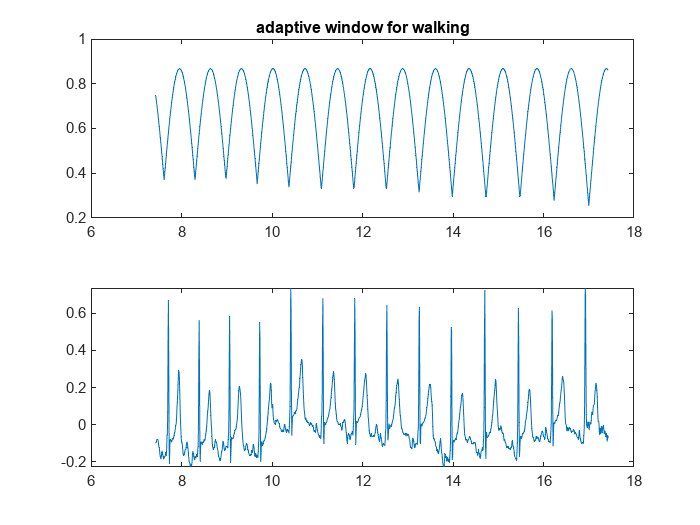

siestatime = 1×19046
    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344


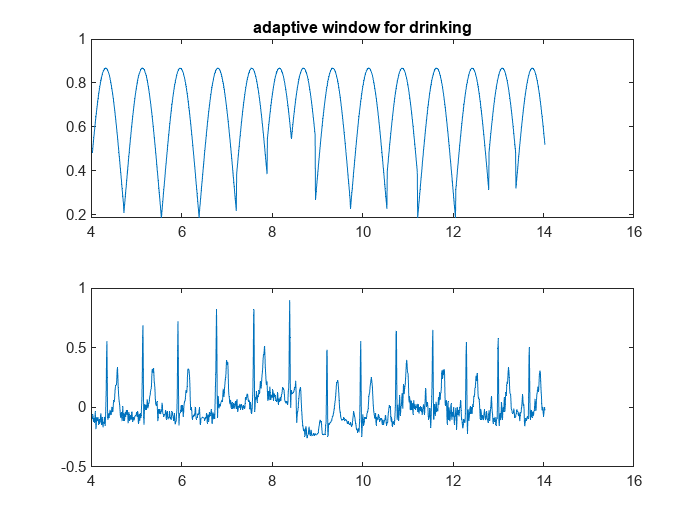

siestatime = 1×18909
    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344


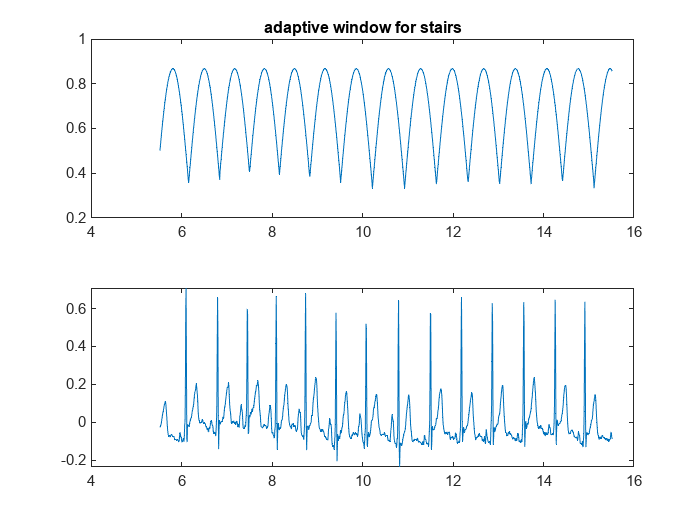

siestatime = 1×8012
    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344


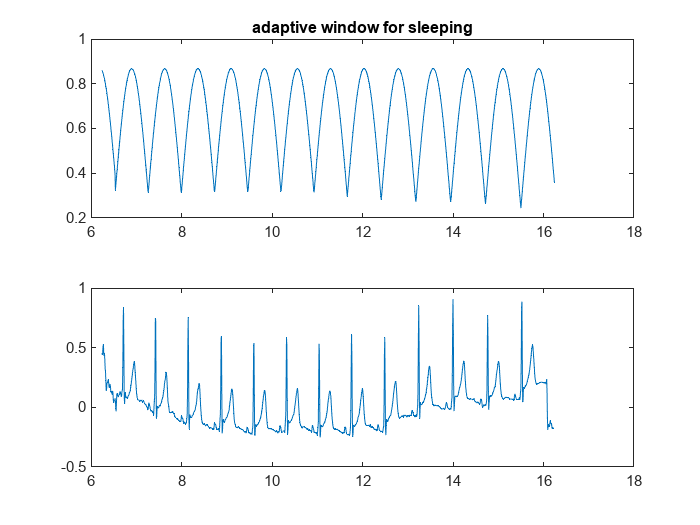

siestatime = 1×18359
    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344


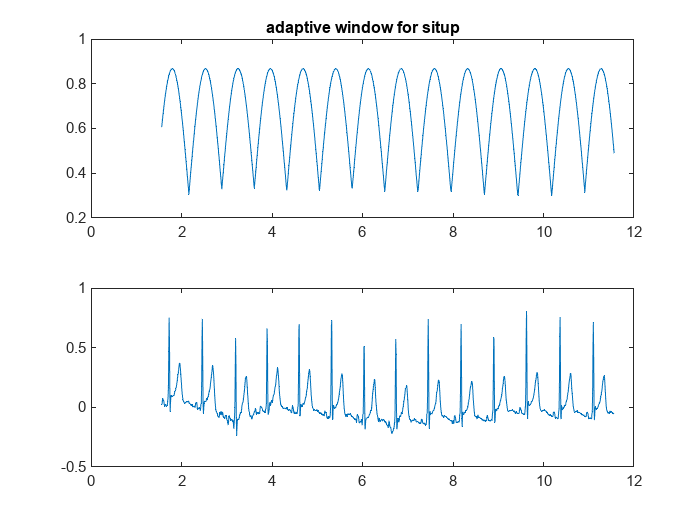

%%
% Siesta

for b=1:5
    casualn = round(rand(1)*1000);
    casualnplus = casualn+FS*10;
    siesta = M_PSI_st{b,1};
    siestatime = [1:length(siesta)]/128%XMEX_sT{b,1}/128
    vx_time = [1:length(VX_task{b})]/128;
    figure(b)
    
    subplot(2,1,1)
    plot(siestatime(casualn:casualnplus),siesta(casualn:casualnplus))
    title("adaptive window for "+ task(b))
    subplot(2,1,2)
    plot(vx_time(casualn:casualnplus),VX_task{b}(casualn:casualnplus))

end


%%
%PPG PER ECG TROVARE E ADATTARE
% CICLO FOR CICLO IF
LS = length(M_PSI_st{4});
LT = length(PPG_SUBsplit{4});

vxecg = PPG_SUBsplit{4}(1:LS);

y = con2seq(vxecg');
u = con2seq(M_PSI_st{4});

UUU = size(u);
XXX = size(y); 

d1 = [1:2];
d2 = [1:2];
narx_net = narxnet(d1,d2,10);
[p,Pi,Ai,t,EW,shift] = preparets(narx_net,u,{},y);
narx_net = train(narx_net,p,t,Pi)
yp = sim(narx_net,p,Pi);
t1 = cell2mat(t);
yp1 = cell2mat(yp);

figure()
subplot(3,1,1)
plot(t1)
legend("train")
subplot(3,1,2)
plot(yp1)
legend("test")
subplot(3,1,3)
plot(vxecg)
legend("true ppg")
e = cell2mat(yp)-cell2mat(t);
figure()
plot(e)
title("error")

%%
sys_interval = [];
for j = 1:5
    for i = 1:size(sysfeet_locs_S{j,1})-1;
        mp = sysfeet_locs_S{j,1}(i,1);
        kk = ((sysfeet_locs_S{j,1}(i+1,1)-sysfeet_locs_S{j,1}(i,1))/2+mp);
        sys_interval = [sys_interval ;kk];
    end
    sys_space_S{j,1} = sys_interval;
    sys_interval = [];
end

%%
%trovare una finestra migliore per ppg
sysXMEX_s = [];
sysM_PSI_s = [];

for j = 1:5
    for i = 1:size(sys_space_S{j,1},1)-1
        
        [sysM_PSI,sysXMEX] = mexihat((sys_space_S{j,1}(i,1)-sys_space_S{j,1}(i+1,1))/128,(sys_space_S{j,1}(i+1,1)-sys_space_S{j,1}(i,1))/128,round(sys_space_S{j,1}(i+1,1)-sys_space_S{j,1}(i,1))+1);
        
        sysM_PSI_s = [sysM_PSI_s,sysM_PSI];
        sysXMEX_s = [sysXMEX_s,sysXMEX];
            
    end
    sysXMEX_sT{j,1} = sysXMEX_s;
    sysM_PSI_st{j,1} = sysM_PSI_s;
    sysXMEX_s = [];
    sysM_PSI_s = [];
end
i
j

%%
for b = 1:5
casualn = round(rand(1)*1000);
casualnplus = casualn+FS*10;
siesta = sysM_PSI_st{b,1};
siestatime = [1:length(siesta)]/128; %XMEX_sT{b,1}/128
vx_time = [1:length(VX_task{b})]/128;
figure(b)

subplot(2,1,1)
plot(siestatime(casualn:casualnplus),siesta(casualn:casualnplus))
title("adaptive window for "+ task(b))
subplot(2,1,2)
plot(vx_time(casualn:casualnplus),PPG_SUBsplit{b}(casualn:casualnplus))

end
%%
%ciclo if per tutte le task
b = 4;
LS = length(sysM_PSI_st{b});
LT = length(PPG_SUBsplit{b});

vxecg = VX_task{b}(1:LS);

y = con2seq(vxecg');
u = con2seq(sysM_PSI_st{b});

UUU = size(u);
XXX = size(y);

d1 = [1:2];
d2 = [1:2];
narx_net = narxnet(d1,d2,10);
[p,Pi,Ai,t,EW,shift] = preparets(narx_net,u,{},y);
narx_net = train(narx_net,p,t,Pi)
yp = sim(narx_net,p,Pi);

figure()
subplot(3,1,1)
t1 = cell2mat(t);
yp1 = cell2mat(yp);
plot(t1)
legend("train")
subplot(3,1,2)
plot(yp1)
legend("test")
subplot(3,1,3)
plot(vxecg)
legend("real ecg")
e = cell2mat(yp)-cell2mat(t);
figure()
plot(e)
title("error")
